% Clear Workspace
clear all
clc

% Read STL File
stl1 = stlread("Test Objects\box.STL");

% Create UniformSliceGeneratorObject
uSGO1 = FlatUniformSliceGenerator(stl1, 6)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [12×3 double]
       numOfElements: 12
              points: [8×3 int64]
      sliceThickness: 6
           slicePath: [0×3 double]
      slicerAccuracy: 0.0100
           slicerTol: 0.0100



test = uSGO1.slice(0)

test =      0     0     0
     0   100     0
   100     0     0
   100     0     0
     0     0     0
   100   100     0
     0   100     0
     0     0     0


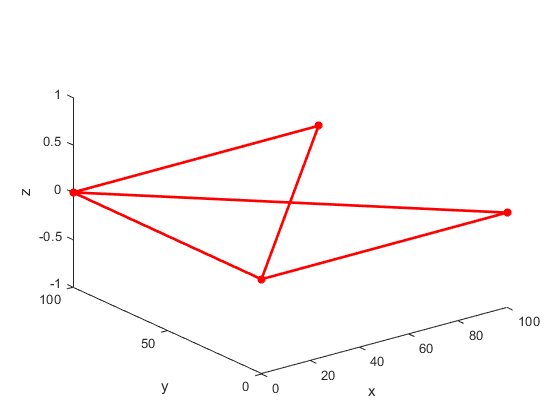

plot3(test(:,1), test(:,2), test(:,3),'-r*','LineWidth',2);
xlabel('x')
ylabel('y')
zlabel('z')


% Generate
figure(3)
uSGO1.generateSlices()

ans =      0     0     0
     0   100     0
   100     0     0
   100     0     0
     0     0     0
   100   100     0
     0   100     0
     0     0     0
     0     0     6
     6     0     6


ans =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [12×3 double]
       numOfElements: 12
              points: [8×3 int64]
      sliceThickness: 6
           slicePath: [160×3 double]
      slicerAccuracy: 0.0100
           slicerTol: 0.0100


op = uSGO1.getSlicePath()

op =      0     0     0
     0   100     0
   100     0     0
   100     0     0
     0     0     0
   100   100     0
     0   100     0
     0     0     0
     0     0     6
     6     0     6


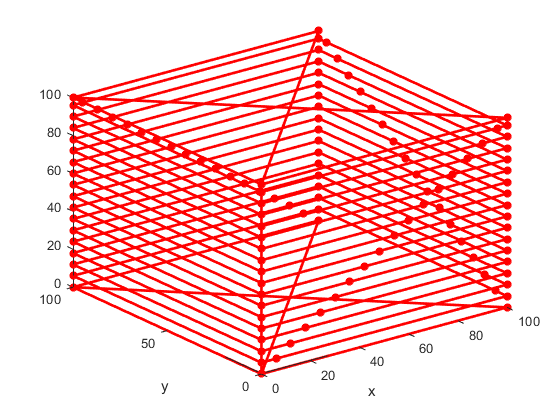


% Show
figure(4)
plot3(op(:,1), op(:,2), op(:,3),'-r*','LineWidth',2);
xlabel('x')
ylabel('y')
view(3);
hold on